clear
table = readtable("../cpp/output/coordinateOutput.csv")

table = 981×6 table
    bombardmentID    particleID    depth         x              y             z     
    _____________    __________    _____    ___________    ___________    __________

         486             0           0        2.476e+08     2.1972e+08    2.7162e+08
          30             0           0       6.7484e+07     -3.029e+08    4.1169e+08
          27             0           0      -2.3214e+08     3.3185e+07    9.4481e+07
         127             0           0      -1.4075e+08    -1.0421e+08    3.3593e+08
         457             0           0       1.3396e+08    -1.7597e+08    4.2199e+08
         666             0           0      -1.7434e+08     4.3581e+07    4.6448e+08
         633             0           0       1.6256e+08     3.7796e+08    4.0687e+08
         6

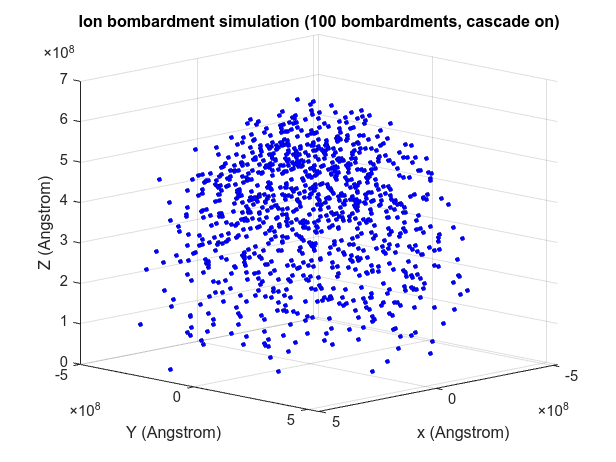

clf; 

filter = false;
    
% Define marker size
marker_size = 10; % Adjust as needed


step = 1;
startidx = 1;
endidx = size(table, 1);

if filter
    target =  0;
    filtered1 = table(table.depth == target, :) 
    % idx = 471742
    x = filtered1.x(startidx:step:endidx);
    y = filtered1.y(startidx:step:endidx);
    z = filtered1.z(startidx:step:endidx);
else
    x = table.x(startidx:step:endidx);
    y = table.y(startidx:step:endidx);
    z = table.z(startidx:step:endidx);
end

scatter3(x, y, z, marker_size, 'Marker', 'o', 'MarkerFaceColor', 'blue', 'MarkerEdgeColor', 'black', 'LineWidth', marker_size/100)
% plot3(x,y,z);
xlabel("x (Angstrom)")
ylabel("Y (Angstrom)")
zlabel("Z (Angstrom)")
title("Ion bombardment simulation (100 bombardments, cascade on)");
view([3,3,1])
% view([0, 0])
grid on;

% xlim([-150,150])
% ylim([-150,150])
% zlim([0, 1000])

opengl info

                          Version: '2.1 Mesa 17.1.3'
                           Vendor: 'Brian Paul'
                         Renderer: 'Mesa X11'
                   MaxTextureSize: 16384
                           Visual: 'Visual 0x88, (RGBA 32 bits (8 8 8 8), Z depth 16 bits, Hardware acceleration, Double buffer, Antialias 0 samples)'
                         Software: 'true'
             HardwareSupportLevel: 'none (known graphics driver issues)'
        SupportsGraphicsSmoothing: 0
    SupportsDepthPeelTransparency: 1
       SupportsAlignVertexCenters: 0
                       Extensions: {152×1 cell}
               MaxFrameBufferSize: 16384



% clf;
% 
% while true
%     THETA0 = pi/6;
%     ALPHA0 = 0;
%     THETA1RELATIVE = rand()*pi;
%     THETA2RELATIVE = 0;
% 
%     [THETA0, ALPHA0] = AMAGIC(THETA0, ALPHA0, THETA1RELATIVE, THETA2RELATIVE)
% 
%     if THETA0 > pi/2
%         disp("Turned!")
%     else
%         disp("Forward.")
%     end
% end

function [THETA1, ALPHA1, THETA2, ALPHA2] = AMAGIC(THETAO, ALPHAO, THETA1RELATIVE, THETA2RELATIVE)
    PI = pi; % Define PI constant

    ALPHA1RELATIVE = rand() * 2 * PI;
    ALPHA2RELATIVE = ALPHA1RELATIVE + PI;

    % For Primary Ion
    X1 = sin(THETA1RELATIVE) * cos(ALPHA1RELATIVE);
    Y1 = sin(THETA1RELATIVE) * sin(ALPHA1RELATIVE);
    Z1 = cos(THETA1RELATIVE);

    Y0 = Y1 * cos(THETAO) + Z1 * sin(THETAO);
    Z0 = -Y1 * sin(THETAO) + Z1 * cos(THETAO);
    X0 = X1;

    Z = Z0;
    X = X0 * sin(ALPHAO) + Y0 * cos(ALPHAO);
    Y = -X0 * cos(ALPHAO) + Y0 * sin(ALPHAO);

    if Z > 0
        THETA1 = atan(sqrt(X ^ 2 + Y ^ 2) / Z);
    elseif Z == 0
        THETA1 = PI / 2;
    else
        THETA1 = PI + atan(sqrt(X ^ 2 + Y ^ 2) / Z);
    end

    if sin(THETA1) ~= 0
        if X > 0
            ALPHA1 = atan(Y / X);
        elseif X == 0
            ALPHA1 = PI - sign(Y) * PI / 2;
        else
            ALPHA1 = PI + atan(Y / X);
        end
    else
        ALPHA1 = 0;
    end

    % For Recoil Target Ion
    X1 = sin(THETA2RELATIVE) * cos(ALPHA2RELATIVE);
    Y1 = sin(THETA2RELATIVE) * sin(ALPHA2RELATIVE);
    Z1 = cos(THETA2RELATIVE);

    Y0 = Y1 * cos(THETAO) + Z1 * sin(THETAO);
    Z0 = -Y1 * sin(THETAO) + Z1 * cos(THETAO);
    X0 = X1;

    Z = Z0;
    X = X0 * sin(ALPHAO) + Y0 * cos(ALPHAO);
    Y = -X0 * cos(ALPHAO) + Y0 * sin(ALPHAO);

    if Z > 0
        THETA2 = atan(sqrt(X ^ 2 + Y ^ 2) / Z);
    elseif Z == 0
        THETA2 = PI / 2;
    else
        THETA2 = PI + atan(sqrt(X ^ 2 + Y ^ 2) / Z);
    end

    if sin(THETA2) ~= 0
        if X > 0
            ALPHA2 = atan(Y / X);
        elseif X == 0
            ALPHA2 = PI - sign(Y) * PI / 2;
        else
            ALPHA2 = PI + atan(Y / X);
        end
    else
        ALPHA2 = 0;
    end
end